# B3シミュレーション

clear;
clc;

%データレートよりもサンプリング周波数の方が十分大きくなければならない
Fs = 10000; %サンプリング周波数[Hz]
Ts = 1/Fs;   %サンプリング周期[s]
Fd = 10;    %データレート[Hz]
Td = 1/Fd;   %データの周期（ナイキスト周期）[s]
A  = 3;     %振幅
TXD = [0 0 1 1 0 0 1 0 0 1 0]  %送信データ

TXD =      0     0     1     1     0     0     1     0     0     1     0


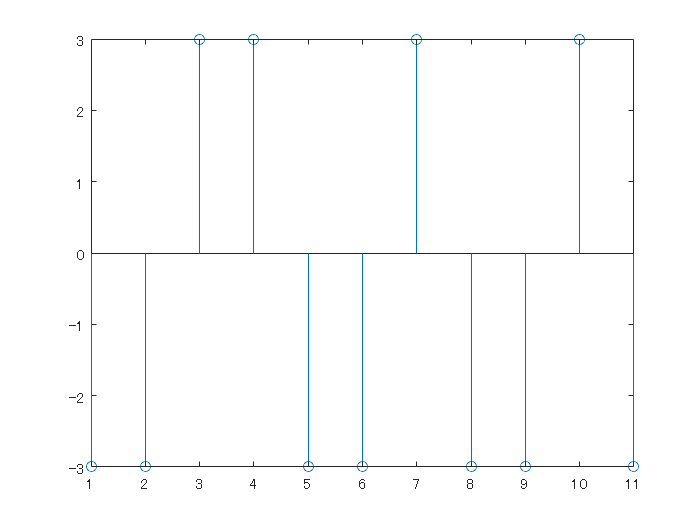

t  = 0:Ts:(numel(TXD)-1)*Td;    %離散時間[s]
%tf = -10*Tc:Ts:10*Tc;           %フィルタインパルス応答の時間列

%信号空間ダイアグラムへのマッピング
BPSK(TXD==0) = -A;
BPSK(TXD==1) = A;
stem(BPSK)

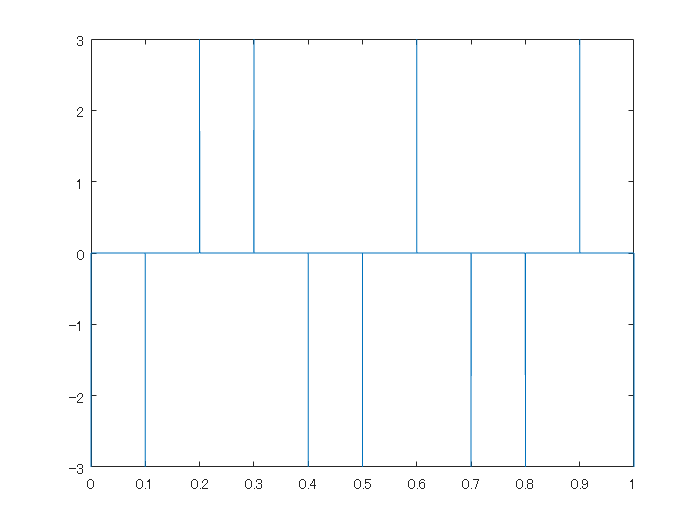


%インパルス列作成
i = 1;
impulse = zeros(1,numel(t));
for data = BPSK
    impulse(i) = data;
    i = i + Fs/Fd;
end
plot(t,impulse);

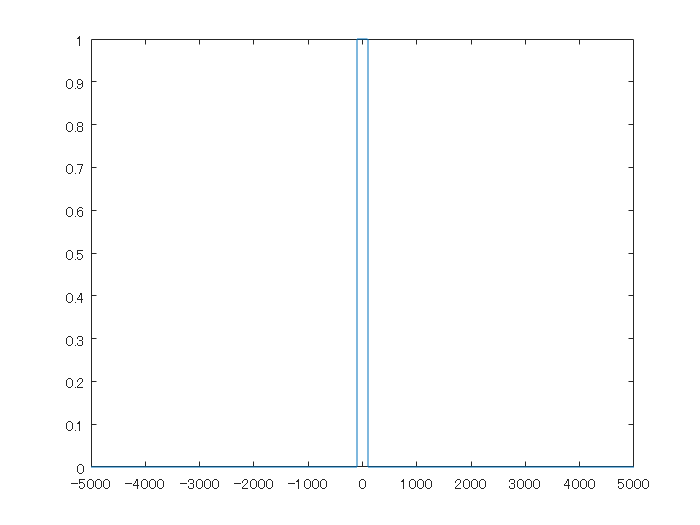


%周波数領域でフィルタを設計
Fc = 1000*Td;
f = linspace(-Fs/2,Fs/2,numel(t));
idealLPF = zeros(1,numel(t));
idealLPF(-Fc<f & f<Fc) = 1;
plot(f,idealLPF);

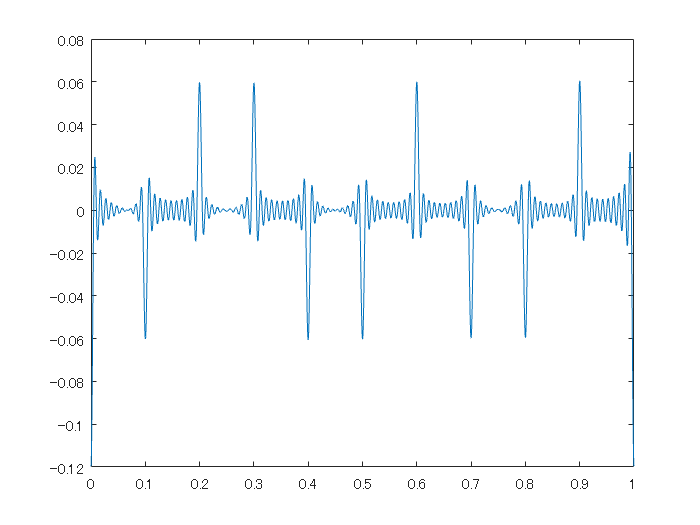

idealLPF = fftshift(idealLPF);

%フィルタ通過
impulse_LPF = ifft(idealLPF.*fft(impulse));
plot(t,real(impulse_LPF));

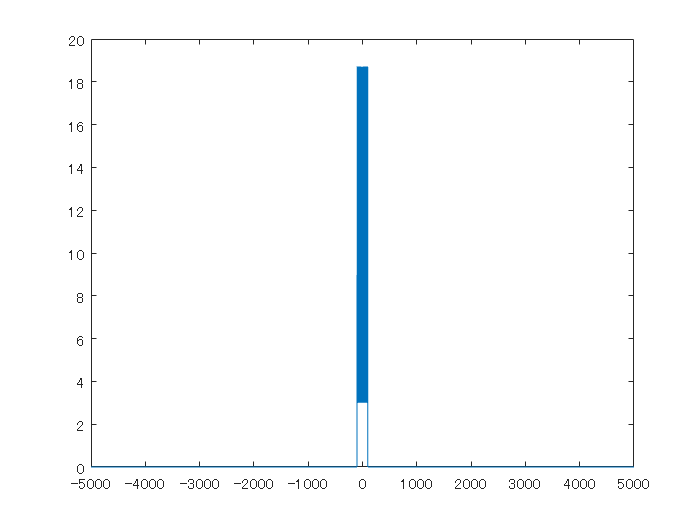

plot(f,abs(fftshift(idealLPF.*fft(impulse))));